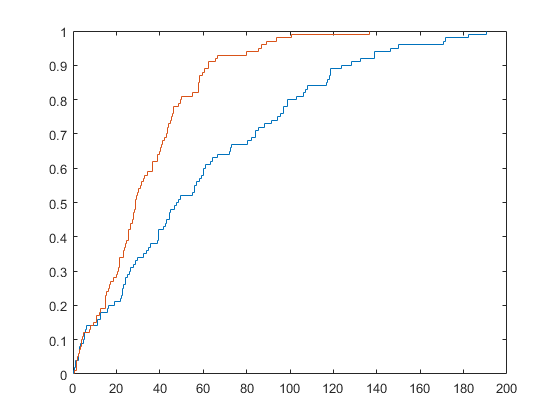

clear all;
close all;

fin = fopen('sgbdold.dat','r');
data_old = fscanf(fin,'%f');
fclose(fin);
fin = fopen('sgbdnew.dat','r');
data_new = fscanf(fin,"%f");
fclose(fin);

[ecdf_old,x_old] = ecdf(data_old);
[ecdf_new,x_new] = ecdf(data_new);

stairs(x_old,ecdf_old);
hold on
stairs(x_new,ecdf_new);